# Matlab Project Assignment

# Task #03

## 1. Q1

close all ; clear ; clc ;
rng(0) ; % reset the random number generator (for reproducibility)
format long eng         

A = 1 ;
f0 = 1/4 ; f_min = 0 ; f_max = 1/2 ;
phi = pi/3 ;
sigma_squared = 0.001 ;
MC = 100000 ; % number of Monte Carlo loops
N = 5 ; % Number of samples in the data
n = (0:N-1)' ; % col vector to represent the index of each sample

%%% Generating of the samples
noise = randn(MC,N)*sqrt(sigma_squared) ; % W ==> N columns of WGN repeated MC rows
% var(noise,1)
signal = A*cos(2*pi*f0.*n + phi) ; % H*A ==> linear model of the signal of interset
X = signal + noise' ; % captured samples with MC times in columns and has N samples in rows

%%% estimators

% 1st aproach: don't estimate the frequency (Get the A and phi correctly)
% f_estimate = f0 ;

% % 2nd approach: estimate the frequency in a crazy vectorized way (generates 3785GB of data ...)
% f = linspace(f_min,f_max,MC) ;
% f = f(2:end-1) ; % trancate the limits
% X3(:,:,length(f)) = X ;
% f3(N,MC,:) = f(:) ;
% I = (1/N) * abs( sum( X.*exp(-1j*2*pi*f_estimate.*n) ) ).^2


% % 3rd approach: estimate the frequency the humble for loop way
f = linspace(f_min,f_max,MC/100) ;
f = f(2:end-1) ; % trancate the limits
%%% The periodogram sounds like a DFT, I wonder if ... 
I = nan*ones(MC,length(f)) ;
for ii = 1:length(f)
    I(:,ii) = (1/N) * abs( sum( X.*exp(-1j*2*pi*f(ii).*n) ) ).^2 ;
end

% load big_I
[~,index] = max(I,[],2)  ; % index of maximum of I(f) along each MC loop
% size(index)
f_estimate_values = f(index) ; % the value of f that resulted in the maximum in each MC loop
% histogram(f_estimate_values)
f_estimate = mean(f_estimate_values)

f_estimate =     249.993473473474e-003



A_estimate = (2/N)* abs( sum(X.*exp(-1j*2*pi*f_estimate.*n)) ) ;
% A
% mean(A_estimate)
% histogram(A_estimate)

phi_estimate = atan(-sum(X.*sin(2*pi*f_estimate.*n))./sum(X.*cos(2*pi*f_estimate.*n))) ;
% phi
% mean(phi_estimate)
% histogram(phi_estimate)


%%% Theoretical variances
var_f_estimate_theory = (24*sigma_squared)/((2*pi)^2*A^2*N*(N-1)) 

var_f_estimate_theory =     30.3963550927013e-006


var_A_estimate_theory = 2*sigma_squared/N 

var_A_estimate_theory =     400.000000000000e-006


var_phi_estimate_theory = (4*sigma_squared*(2*N-1))/(A^2*N*(N+1)) 

var_phi_estimate_theory =     1.20000000000000e-003



results_var = [var_A_estimate_theory var_f_estimate_theory var_phi_estimate_theory ; var(A_estimate) var(f_estimate_values) var(phi_estimate)] 

results_var =     400.000000000000e-006    30.3963550927013e-006    1.20000000000000e-003
    389.709034711724e-006    8.99251827906217e-006    486.734453869912e-006


results_mean = [A f0 phi ; mean(A_estimate) mean(f_estimate_values) mean(phi_estimate)] 

results_mean =     1.00000000000000e+000    250.000000000000e-003    1.04719755119660e+000
    916.724555046527e-003    249.993473473474e-003    857.231348328749e-003


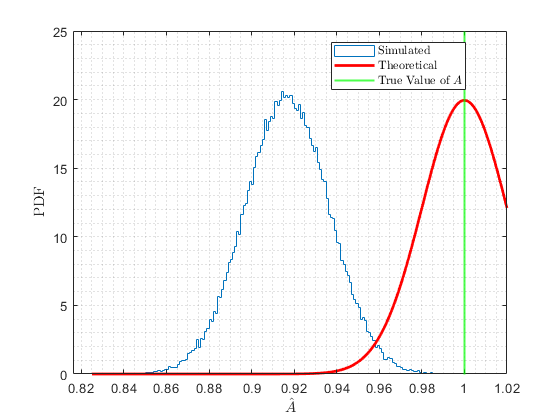

% Plotting Spagetti
% my_uniform = @(mu,sigma2) (mu-sqrt(12)/2*sqrt(sigma2)) + sqrt(12)*sqrt(sigma2)*rand(1,100) ;
fig1 = figure ;
A1 = histogram(A_estimate,'Normalization','pdf','DisplayStyle',"stairs") ;
hold on
A2 = linspace(min(A1.BinLimits(1),(A-sqrt(var_A_estimate_theory))), max(A1.BinLimits(2),A+sqrt(var_A_estimate_theory)),200) ; % range of x for theoretical results
A_theor_PDF = normpdf(A2,A,sqrt(var_A_estimate_theory)) ;
plot(A2, A_theor_PDF,'r-','Linewidth',2) ;
xline(A,'-g','Linewidth',1.5) ; % true value
hold off
grid minor
xlabel('$\hat{A}$','interpreter','latex') ;
ylabel('PDF','interpreter','latex') ;
legend('Simulated','Theoretical','True Value of $A$','interpreter','latex','Location','best') ;

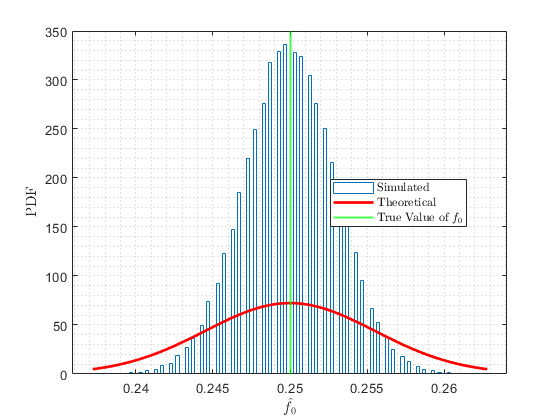


fig2 = figure ;
f1 = histogram(f_estimate_values,'Normalization','pdf','DisplayStyle',"stairs") ;
hold on
f2 = linspace(min(f1.BinLimits(1),(f0-sqrt(var_f_estimate_theory))), max(f1.BinLimits(2),f0+sqrt(var_f_estimate_theory)),200) ; % range of x for theoretical results
f_theor_PDF = normpdf(f2,f0,sqrt(var_f_estimate_theory)) ;
plot(f2, f_theor_PDF,'r-','Linewidth',2) ;
xline(f0,'-g','Linewidth',1.5) ; % true value
hold off
grid minor
xlabel('$\hat{f}_0$','interpreter','latex') ;
ylabel('PDF','interpreter','latex') ;
legend('Simulated','Theoretical','True Value of $f_0$','interpreter','latex','Location','best') ;

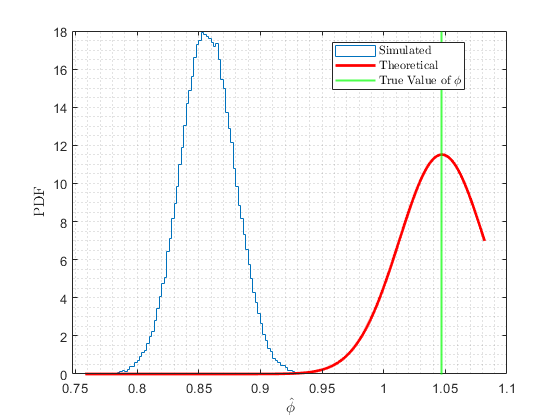


fig3 = figure ;
phi1 = histogram(phi_estimate,'Normalization','pdf','DisplayStyle',"stairs") ;
hold on
phi2 = linspace(min(phi1.BinLimits(1),(phi-sqrt(var_phi_estimate_theory))), max(phi1.BinLimits(2),phi+sqrt(var_phi_estimate_theory)),200) ; % range of x for theoretical results
phi_theor_PDF = normpdf(phi2,phi,sqrt(var_phi_estimate_theory)) ;
plot(phi2, phi_theor_PDF,'r-','Linewidth',2) ;
xline(phi,'-g','Linewidth',1.5) ; % true value
hold off
grid minor
xlabel('$\hat{\phi}$','interpreter','latex') ;
ylabel('PDF','interpreter','latex') ;
legend('Simulated','Theoretical','True Value of $\phi$','interpreter','latex','Location','best') ;




% exportgraphics(fig1,'plot_Q1_A.pdf')
% exportgraphics(fig2,'plot_Q1_f.pdf')
% exportgraphics(fig3,'plot_Q1_phi.pdf')

## 2. Q2

close all ; clear ; clc ;
rng(0) ; % reset the random number generator (for reproducibility)
% format long eng         

A = 1 ;
M = 2 ;
sigma_squared = 0.001 ;
f0 = 1/4 ;
phi0 = pi/3 ;
iter = 10 ;
n = (-M:M)' ; % col vector to represent the index of each sample

%%% Generating of the samples
noise = randn(length(n),1)*sqrt(sigma_squared) ; % W ==> N columns of WGN repeated MC rows
% var(noise)
signal = A*cos(2*pi*f0.*n + phi0) ; % H*A ==> linear model of the signal of interset
X = signal + noise ; % captured samples with MC times in columns and has N samples in rows



%%% estimators
f = nan*ones(1,iter+1) ;
phi = nan*ones(1,iter+1) ;

f(1) = 0.001 ; % initial guess
phi(1) = 0.001 ; % initial guess

for ii =1:iter
    f(ii+1) = f(ii) - (3/(4*pi*M^3))*sum( n.*X.*sin(2*pi*f(ii).*n+phi(ii)) ) ;
    phi(ii+1) = phi(ii) - (1/M)*sum( X.*sin(2*pi*f(ii).*n+phi(ii)) ) ;
end

f0

f0 =     250.000000000000e-003


f_value = f(end)

f_value =     238.357924754949e-003



phi0

phi0 =     1.04719755119660e+000


phi_value = phi(end)

phi_value =     902.693900681200e-003


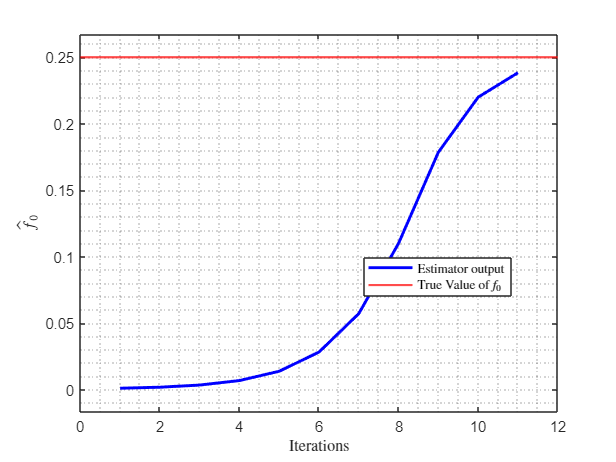



% MORE Plotting Spagetti
fig1 = figure ;
plot(1:iter+1,f,'b-','Linewidth',2) ;
yline(f0,'-r','Linewidth',1.5) ; % true value
hold off
grid minor
ylim padded
xlabel('Iterations','interpreter','latex') ;
ylabel('$\hat{f}_0$','interpreter','latex') ;
legend('Estimator output','True Value of $f_0$','interpreter','latex','Location','best') ;

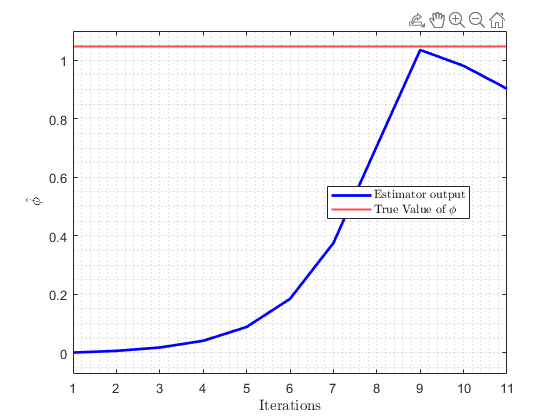



fig2 = figure ;
plot(1:iter+1,phi,'b-','Linewidth',2) ;
yline(phi0,'-r','Linewidth',1.5) ; % true value
hold off
grid minor
ylim padded
xlabel('Iterations','interpreter','latex') ;
ylabel('$\hat{\phi}$','interpreter','latex') ;
legend('Estimator output','True Value of $\phi$','interpreter','latex','Location','best') ;


% exportgraphics(fig1,'plot_Q2_f.pdf')
% exportgraphics(fig2,'plot_Q2_phi.pdf')


